1

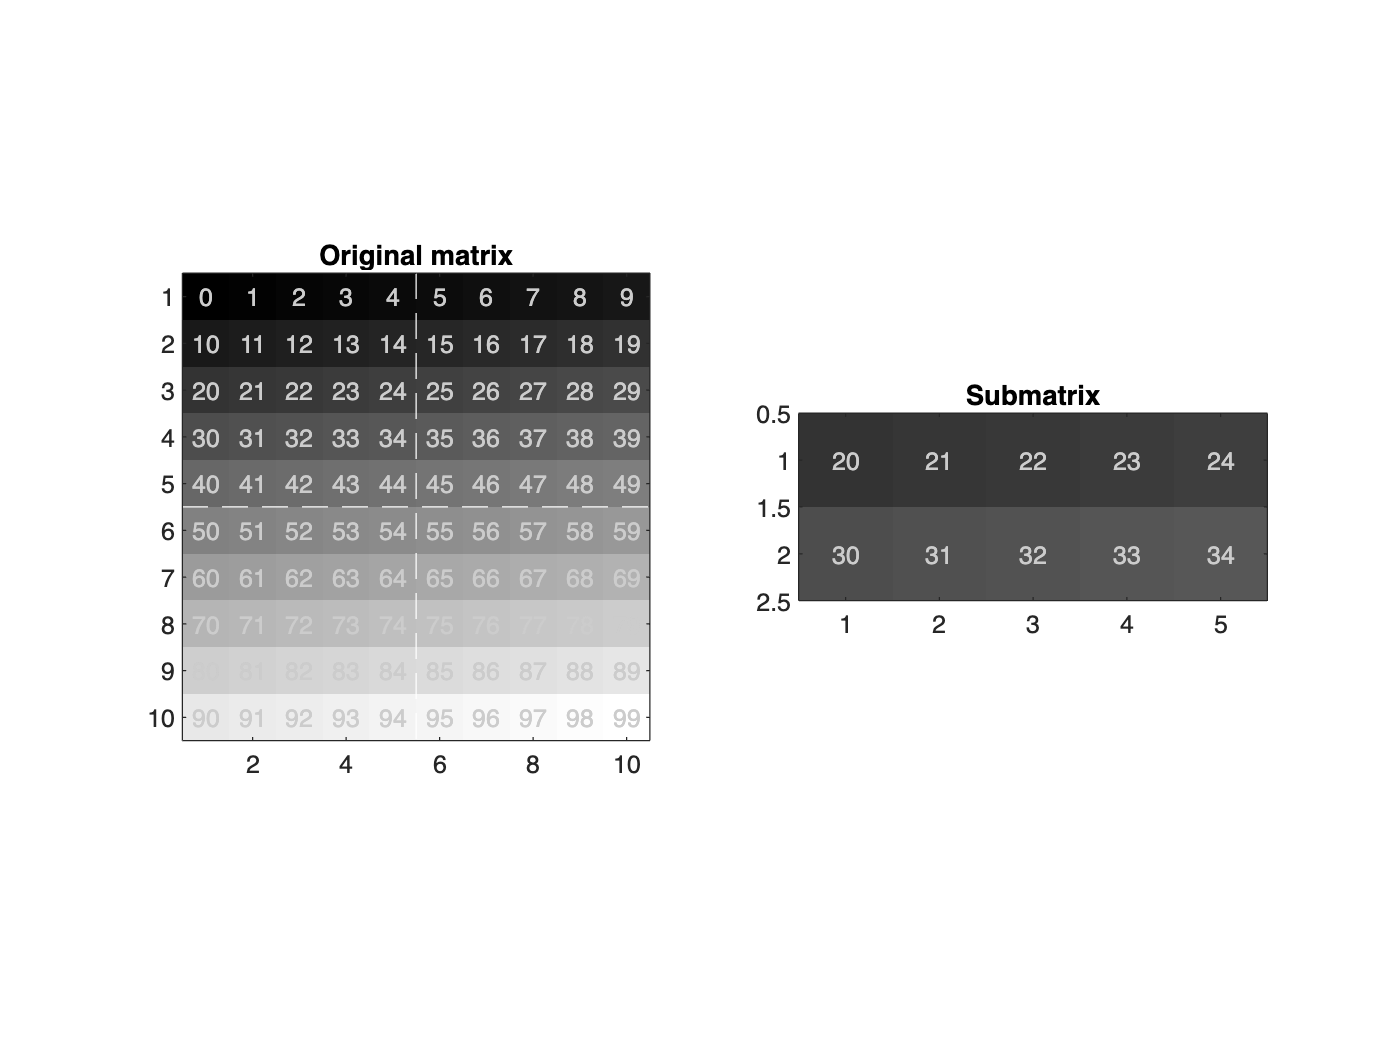

clc; clear; close all;

%%%%%%%%%%% ToDo %%%%%%%%%%%
% Create the matrix
C = reshape(0:99, 10, 10)';

% Extract submatrix
% Generate function for extract submatrix
slice_indices = [3, 4, 1, 5]; % start row index, end row index, start col index, end col index
C_1 = GenSubmatrix(C, slice_indices);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Visualize the matrices as maps
figure;

% Original matrix visualization
subplot(1, 2, 1);
imagesc(C, [0, max(C(:))]); % Match color scaling with the Python version
colormap('gray');
axis equal tight;
title('Original matrix');
hold on;
% White dashed lines
plot([5.5, 5.5], [0.5, 10.5], 'w--');
plot([0.5, 10.5], [5.5, 5.5], 'w--');
hold off;
% Adding text labels
for i = 1:size(C, 1)
    for j = 1:size(C, 2)
        text(j, i, num2str(C(i, j)), 'Color', [0.8, 0.8, 0.8], 'HorizontalAlignment', 'center');
    end
end

% Submatrix visualization
subplot(1, 2, 2);
imagesc(C_1, [0, max(C(:))]); % Ensure consistent color scaling
colormap('gray');
axis equal tight;
title('Submatrix');
% Adding text labels for the submatrix
for i = 1:size(C_1, 1)
    for j = 1:size(C_1, 2)
        text(j, i, num2str(C_1(i, j)), 'Color', [0.8, 0.8, 0.8], 'HorizontalAlignment', 'center');
    end
end


%%%%%%%%%%% ToDo %%%%%%%%%%%
% write code here
% input : matrix, start row index, end row index, start col index, end col index
% Output : submatrix
function sub_matrix = GenSubmatrix(origin_matrix, slice_info)
    [st_row, ed_row, st_col, ed_col] = deal(slice_info(1), slice_info(2), slice_info(3), slice_info(4));

    sub_matrix = origin_matrix(st_row:ed_row, st_col:ed_col);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

2

clc; clear; close all;

% Test the function
M1 = ones(6, 4);
M2 = reshape(0:23, [6, 4]);

C = addMatrices(M1, M2);
disp(C);

     1     7    13    19
     2     8    14    20
     3     9    15    21
     4    10    16    22
     5    11    17    23
     6    12    18    24




%%%%%%%%%%% ToDo %%%%%%%%%%%
% input: two matrix with same size
% output: summation result
function C = addMatrices(A, B)

  % Check that both matrices have the same size
  [rows_A, cols_A] = size(A);
  %[rows_B, cols_B] = size(B);
  if ~isequal(size(A), size(B))
      error('Please put same size matricies');
  end
  % Summation
  
  C = zeros(rows_A, cols_A);

  for r = 1:rows_A
      for c = 1:cols_A
          C(r,c) = A(r,c) + B(r,c);
      end
  end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

3

clc; clear; close all;
% Generate two matrices
m = 4;
n = 6;
k = 4;
input_matrix_1 = randn(m, n);
input_matrix_2 = randn(n, m);

% Build up the product matrix element-wise
% write code here

%%%%%%%%%%% ToDo %%%%%%%%%%%
if k == size(input_matrix_1, 1) && size(input_matrix_2, 2)
    mulMatrix01 = matrixMultiplication(input_matrix_1, input_matrix_2, m);
else
    error('Please input valid Matrix');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Implement matrix multiplication directly
mulMatrix02 = input_matrix_1 * input_matrix_2;

disp(mulMatrix01);

   -6.3825   -0.2838   -0.3886   -4.4701
    3.5907    1.6707    2.8670    1.5141
   -1.3400    1.7502   -2.1527   -0.3621
   -2.4712    2.3078    0.4377   -2.4097



disp(mulMatrix02);

   -6.3825   -0.2838   -0.3886   -4.4701
    3.5907    1.6707    2.8670    1.5141
   -1.3400    1.7502   -2.1527   -0.3621
   -2.4712    2.3078    0.4377   -2.4097




% write code here
% input : two matrix
% output : one matrix (Result of multiplication)
% Check if the two MATRIX is available for dot product

%%%%%%%%%%% TODO %%%%%%%%%%%
function mulMatrix = matrixMultiplication(inputMatrix01, inputMatrix02, m)
    for rowi = 1:m
        for coli = 1:m
            mulMatrix(rowi, coli) = dot(inputMatrix01(rowi, :), inputMatrix02(:, coli));
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

4.

clc; clear; close all;
% Test the function with a symmetric matrix
% sym matrix
S = [1, 2, 3; 2, 5, 6; 3, 6, 9];

% not sym matrix
% S = [1, 1, 2; 2, 5, 5; 7, 6, 9];

isSym = isMatrixSymmetric(S);
disp(['Is the matrix symmetric? ', num2str(isSym)]);

Is the matrix symmetric? 1



%%%%%%%%%%% ToDo %%%%%%%%%%%
function isSymmetric = isMatrixSymmetric(S)
  % Difference between matrix and its transpose
  mat_diff = S - S';
  SSE = norm(mat_diff);

  % SSE_2 = sum(mat_diff(:).^2);
  % disp(SSE_2)

  % Check whether sum of squared errors (SSE) is smaller than a threshold
  if SSE > 0
      isSymmetric = 0;
  else
      isSymmetric = 1;
  end

  % Output TRUE if sse is tiny; FALSE means the matrix is asymmetric

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%